**Projekt Bild**

**Karolina Utsi & Theo Wikström**

**Punkt 1 - Skapa spatiala bilder från 3D raw data (via iFFT).**

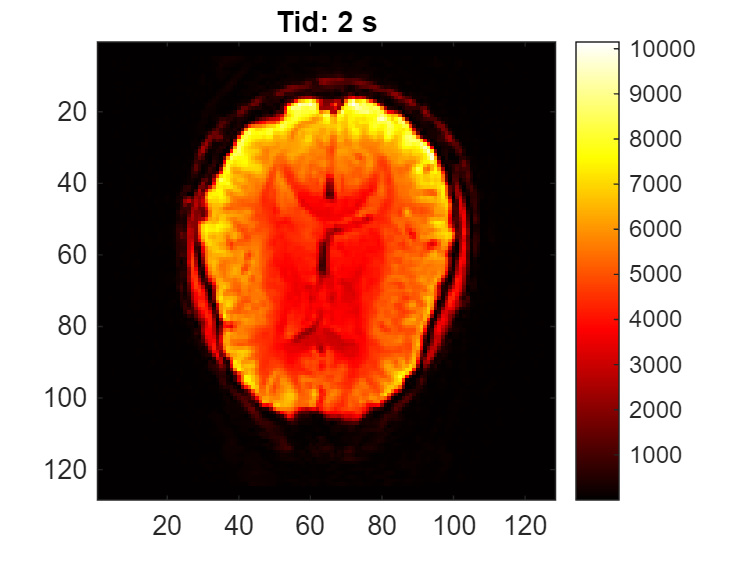

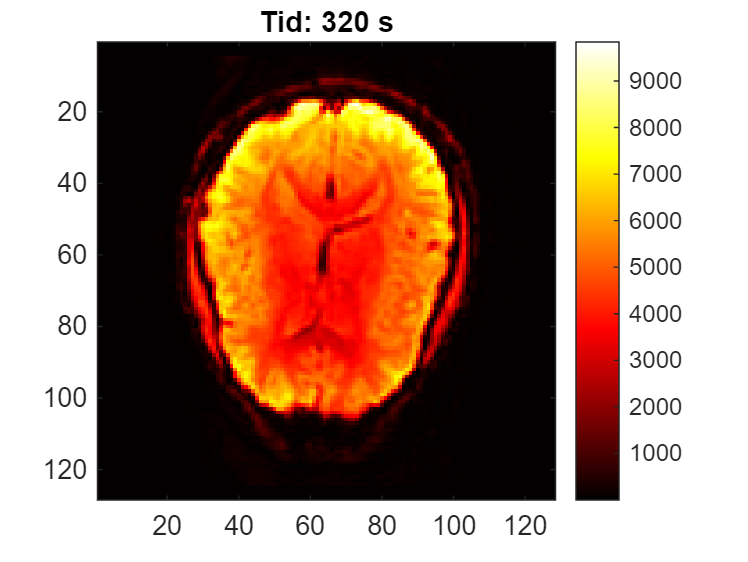

%% Load raw k-space data
load('Data/rawData.mat');  % justera sökvägen om det behövs

%% Skapa 3D-bilder via iFFT
% Antag att rawData heter 'kSpace' i filen och har dimensioner [X Y Z T]
% X, Y, Z = rumsliga dimensioner, T = antal tidssteg (160)

numTimepoints = size(kSpace,4);       % 160
img = zeros(size(kSpace));            % 4D-array för bilder (X x Y x Z x T)

for t = 1:numTimepoints
    k0 = kSpace(:,:,:,t);             % plocka ut k-space vid tid t
    img(:,:,:,t) = abs(fftshift(ifftn(ifftshift(k0))));  % iFFT och absolutvärde
end

%% Visa mittsnitt i z-led som animation
z_mid = round(size(img,3)/2);         % mitt i z-led

figure; 
for t = 1:numTimepoints
    imagesc(img(:,:,z_mid,t));
    colormap hot; 
    axis image; 
    colorbar;
    title(['Tid: ' num2str(t*2) ' s']);  % 2 s per bild
    pause(0.1);  % justera hastighet på animationen
end

**Punkt 2 - Bilderna kan innehålla små rörelseförändringar mellan mätpunkterna. Dessa kan korrigeras med ”motion correction”/”Image registration” i Matlab.**

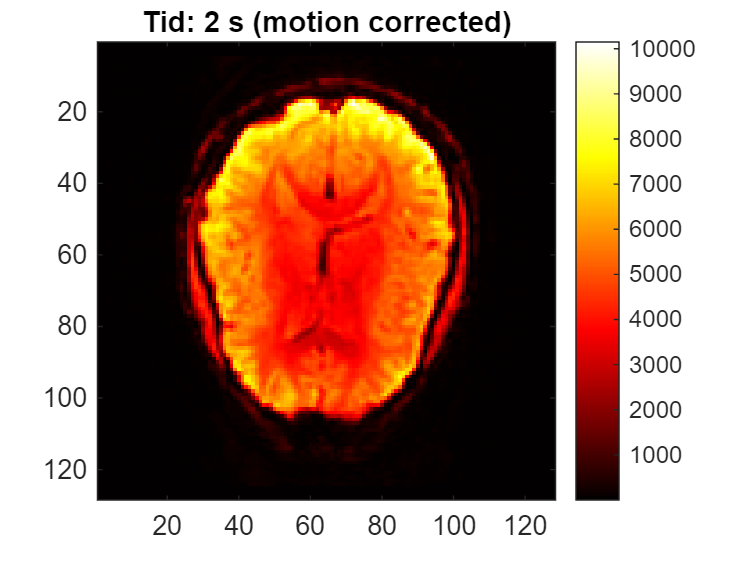

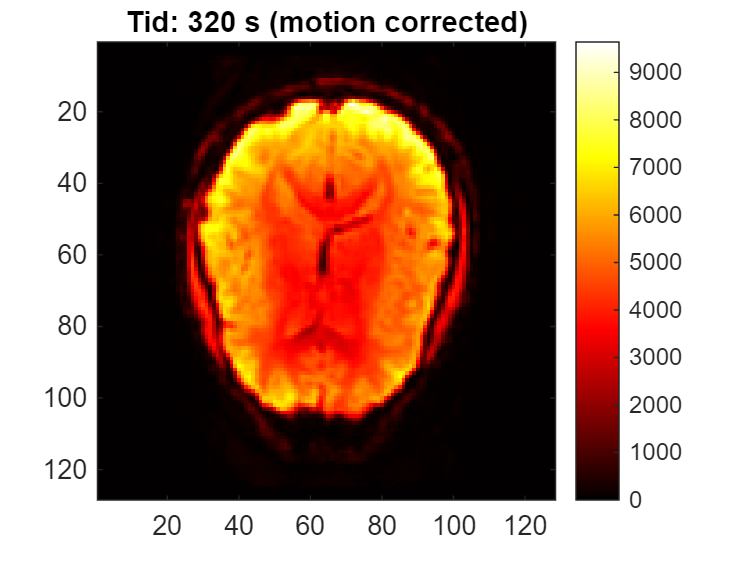


%% Motion correction på mittsnitt i z-led
z_mid = round(size(img,3)/2);             % mitt i z-led
img_slice = squeeze(img(:,:,z_mid,:));    % X x Y x T

fixed = img_slice(:,:,1);                 % första bilden som referens
img_corrected = zeros(size(img_slice));   % array för korrigerade bilder

% Skapa optimizer och metric
[optimizer, metric] = imregconfig('monomodal');  % passar bra för MRI

for t = 1:size(img_slice,3)
    moving = img_slice(:,:,t);
    
    % Rigid image registration
    tform = imregtform(moving, fixed, 'rigid', optimizer, metric);
    
    % Applicera transform och spara korrigerad bild
    img_corrected(:,:,t) = imwarp(moving, tform, 'OutputView', imref2d(size(fixed)));
end

%% Visa animation av korrigerade bilder
figure;
for t = 1:size(img_corrected,3)
    imagesc(img_corrected(:,:,t));
    colormap hot;
    axis image;
    colorbar;
    title(['Tid: ' num2str(t*2) ' s (motion corrected)']);
    pause(0.10);
end

**Punkt 3 - Bilderna innehåller brus som behöver filtreras bort...**

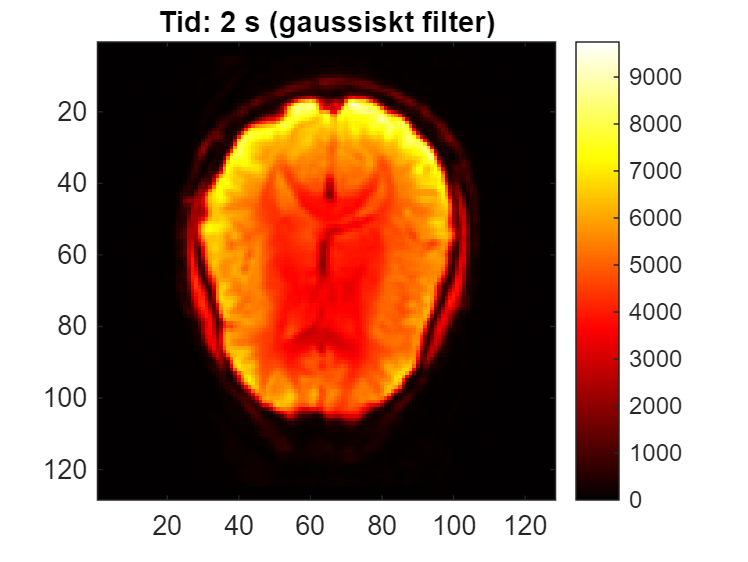

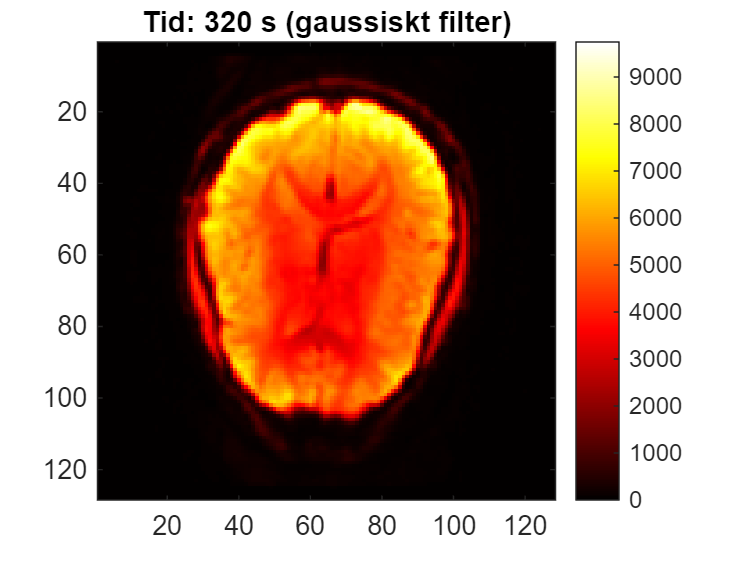

%% Load raw k-space data
load('Data/rawData.mat');  % justera sökvägen om det behövs

%% Parametrar
numTimepoints = size(kSpace,4);       % antal tidssteg (160)
[X, Y, Z] = size(kSpace(:,:,:,1));

img_filtered = zeros(X,Y,Z,numTimepoints);  % 4D-array för bilder efter filtrering

%% Skapa 3D-gaussiskt lågpassfilter
a = 0.3;  % lite större värde än tidigare → mindre suddig
[x, y, z] = ndgrid(linspace(-0.5,0.5,X), linspace(-0.5,0.5,Y), linspace(-0.5,0.5,Z));
gaussFilter = exp(-(x.^2 + y.^2 + z.^2)/(2*a^2));

%% Applicera filter i frekvensplanet och iFFT
for t = 1:numTimepoints
    k0 = kSpace(:,:,:,t);                 % rå k-space data
    kFilt = k0 .* gaussFilter;            % filtrera i frekvensplanet
    img_filtered(:,:,:,t) = abs(fftshift(ifftn(ifftshift(kFilt))));  % iFFT
end

%% Animation av mittsnitt i z-led
z_mid = round(Z/2);                       % mitt i z-led
figure;
for t = 1:numTimepoints
    imagesc(img_filtered(:,:,z_mid,t));
    colormap hot;       % tydligare färger än gray
    axis image;
    colorbar;
    caxis([0 max(img_filtered(:))]);  % fixar kontrasten → hjärnstrukturen syns bättre
    title(['Tid: ' num2str(t*2) ' s (gaussiskt filter)']);
    pause(0.05);
end

**Punkt 4 - Skapa en tidsvektor som motsvarar hjärnans aktiveringsnivå. Utgå från aktiveringstider och HRF.**

**Punkt 5 - Hitta en korrelation mellan aktiveringssignal och voxlar (3D-pixlar).**

%...

**Punkt 6 - Rapportera funktionen av er metod...**